# **Кинематика точки**

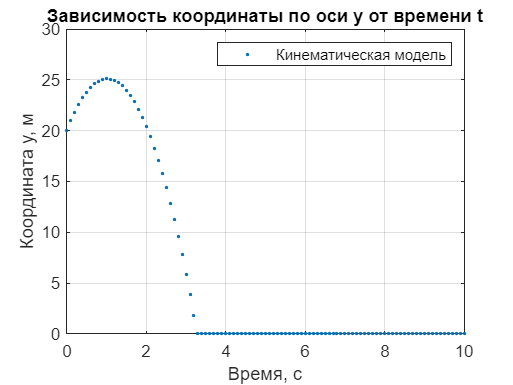

g = 9.8;
y0 = 20;
v0 = 10;

dt = 0.1;
t = 0:dt:10;

y = y0 + v0 * t - g * t.^2 / 2;
y(y <= 0) = 0;

plot(t, y, '.');
xlabel('Время, с');
ylabel('Координата y, м');
title('Зависимость координаты по оси y от времени t');
legend('Кинематическая модель');
grid on;

# **Динамика точки**

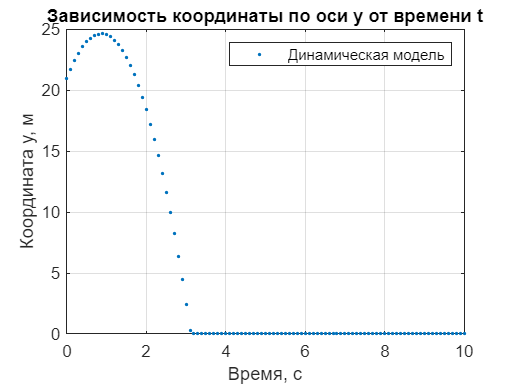

g = 9.8;
y0 = 20;
v0 = 10;

dt = 0.1;
t = 0:dt:10;

v = v0 + cumsum(repmat(-g, size(t)) * dt);
y = y0 + cumsum(v * dt);
y(y <= 0) = 0;

plot(t, y, '.');
xlabel('Время, с');
ylabel('Координата y, м');
title('Зависимость координаты по оси y от времени t');
legend('Динамическая модель');
grid on;

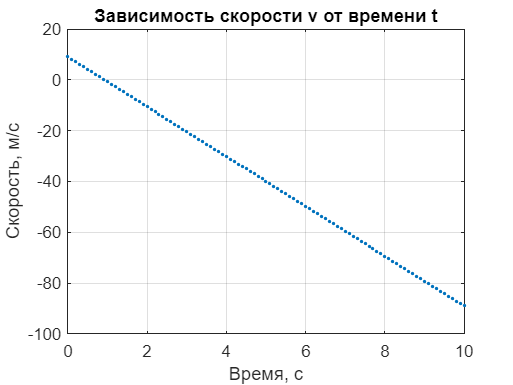


plot(t, v, '.');
xlabel('Время, с');
ylabel('Скорость, м/c');
title('Зависимость скорости v от времени t');
grid on;

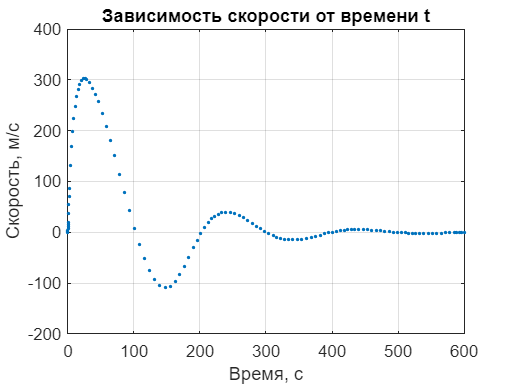

clear variables;
u0 = [0, 0];
[t, u] = ode45(@fcn, [0 600], u0);

y = u(:, 1);
v = u(:, 2);

plot(t, v, '.');
xlabel('Время, с');
ylabel('Скорость, м/с');
title('Зависимость скорости от времени t');
grid on;

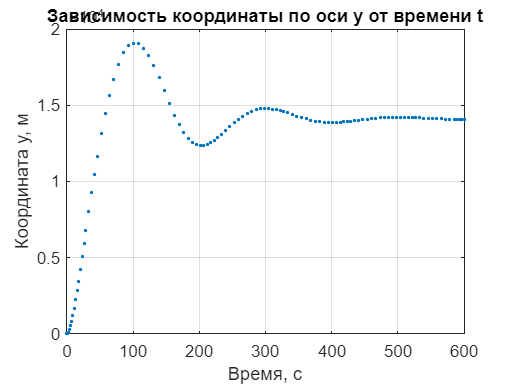


plot(t, y, '.');
xlabel('Время, с');
ylabel('Координата y, м');
title('Зависимость координаты по оси y от времени t');
grid on;

function rho = airDensity(y)
    T = 300;
    R = 8.31;
    M = 0.029;
    g = 9.8;
    rho0 = 1;

    rho = rho0 * exp((-M * g * y)/(R * T));
end

function dudt = fcn(t, u)

    y = u(1);
    v = u(2);

    dudt = zeros(size(u));
    m = 0.2;
    V = 1;
    g = 9.8;
    k = 0.02;

    F_A = airDensity(y) * g * V;
    F_R = - k * v * airDensity(y);
    F_G = - m * g;

    dudt(1) = v;
    dudt(2) = (F_G + F_R + F_A) / m;

end



